clc; clear; close all
load("matrix.mat");
Mat = matrix;

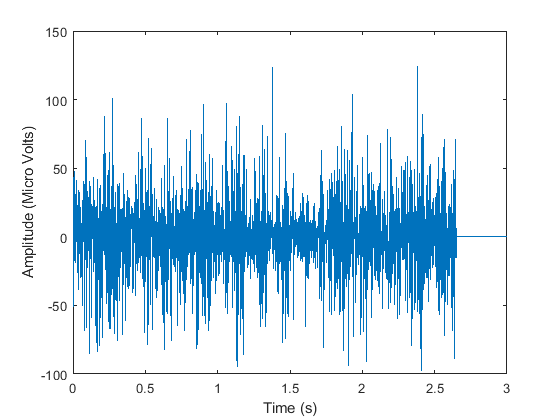


%Section 1: Plotting a sample EEG signal and declaring variables 

% 1) Creating a time vector based on the frequency of 1000 Hz

t = 0:1/1000:1/1000*3000 - 1/1000;
    
% 2) Plotting sample sleep signal

plot(t,Mat(1:3000,1))
xlabel( "Time (s)" );
ylabel( "Amplitude (Micro Volts)" );



% 3) Declaring all the variables for the models and testing sets
    % Given the constrains of our model, it only can take 66*10^6
    % data points. Therefore, that is the size of the training set.
    % the rest of the data is used as a testing set.
k= 66;
training_set_attribute = Mat(1:(10^6)*k,1);
training_set_labels    = Mat(1:(10^6)*k,2);
testing_set_attribute  = Mat((10^6)*k+1:end,1);
testing_set_labels     = Mat((10^6)*k+1:end,2);
    

% 2) Plotting sample night sleep signal
%plot(t,Mat(1:6431640,1)); % here we are plotting the first 6,431,640 points
plot(1:10001,Mat(70000000:70010000,1))
xlabel( "Time (s)" );
ylabel( "Amplitude (Micro Volts)" );


%Section 3: Machine learning model to predict sleep staging 
    % In this section we will create a machine learning models to predict
    % sleep staging.

% 1 ) Linear Discriminant Analysis
    % In this case lda is the Linear Discriminant Analysis model for our data
lda = fitcdiscr( training_set_attribute, training_set_labels);
    % Confusion Matrix for the decision tree model 
ldaReSubErr = resubLoss(lda) ;
fprintf('Model error in predicting training set is %4.3f \n', ldaReSubErr);

LDA error is 0.290 


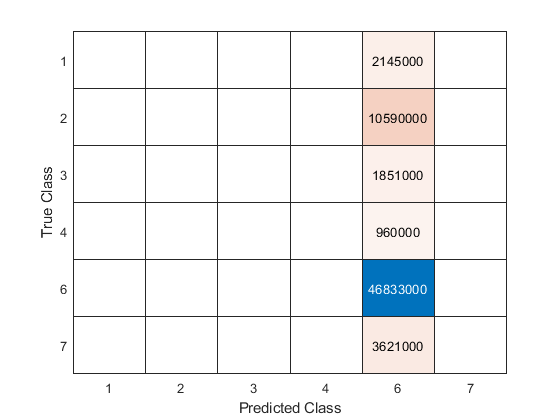

lda_classification = resubPredict(lda);
confusionchart(training_set_labels,lda_classification);


%Section 4: Data prediction of 
predicted_labels = predict(lda,testing_set_attribute);
accuracy = (1 - sum(predicted_labels ~= testing_set_labels)/length(Mat(:,1)) )*100;
fprintf('Our model accuracy predicting the testing set is %4.3f \n', accuracy);

Our model accuracy predicting the testing set is 88.080 
